# **RT-QIBC analysis**

**FarRed1: chromatin-bound protein stain**

**FarRed2: EdU**

**YFP1: APC/C reporter intensity (residual after preextraction)**

**POI(:,2): APC/C inactivation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
global framesPerHr numFrames conditions;
conditions = {
        'PCNA no dox',6,2:4,1:4,[0 0 0],'Dox-','PCNA'; %1      
        'PCNA dox',6,5:11,1:4,[0 0 0],'Dox+','PCNA'; %1 
        
        'CDC45 no dox',2,2:4,1:4,[0 0 0],'Dox-','CDC45'; %1      
        'CDC45 dox',2,5:11,1:4,[0 0 0],'Dox+','CDC45'; %1    

        'POLA2 no dox',3,2:4,1:4,[0 0 0],'Dox-','POLA2'; %1      
        'POLA2 dox',3,5:11,1:6,[0 0 0],'Dox+','POLA2'; %1    
        
        'POLD2 no dox',4,2:4,1:6,[0 0 0],'Dox-','POLD2'; %1      
        'POLD2 dox',4,5:11,1:6,[0 0 0],'Dox+','POLD2'; %1    
        
        'POLE2 no dox',5,2:4,1:6,[0 0 0],'Dox-','POLE2'; %1      
        'POLE2 dox',5,5:11,1:6,[0 0 0],'Dox+','POLE2'; %1   

    };



load([dataDir filesep 'C194_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 1.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

**Set thresholds based on treatment 1**

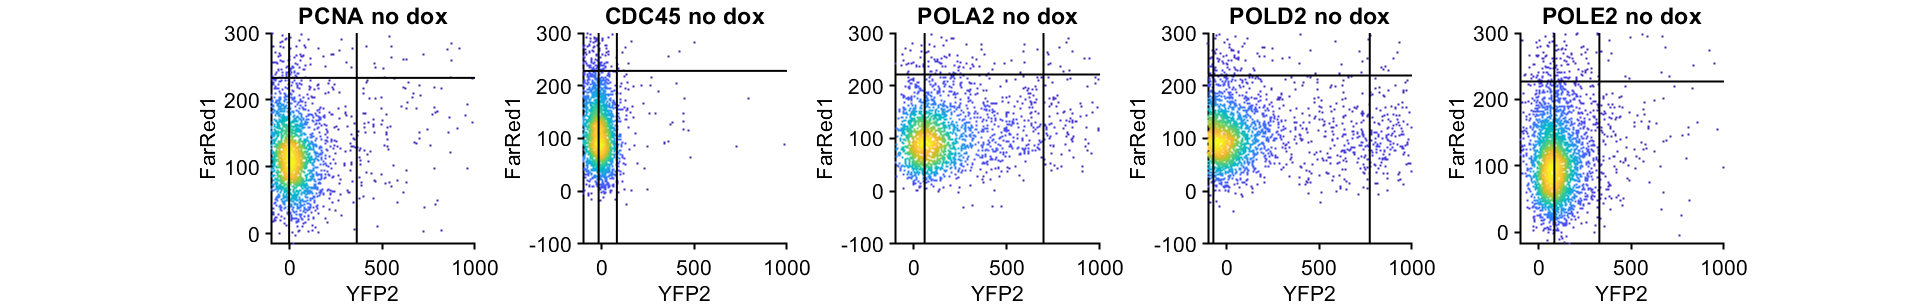

conds=[1 3 5 7 9];
f1 = figure('Units', 'Inches', 'Position', [0, 0, 5*length(conds), 4]);

for i = 1:length(conds)
    
    cond = conds(i);
    xval = 'YFP2';
    yval = 'FarRed1';
    
    xdata = S(cond).(xval) - S(cond).YFP2cyt;
    ydata = S(cond).(yval) ;
   
    inds = log2(S(cond).dna) < 20 & isnan(S(cond).POI(:,2)) & ydata < 300 & S(cond).YFP3 < 10 ;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    inds = xdata < 1000;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    [kval,xv]=ksdensity(xdata);
    modeX=xv(find(kval==max(kval),1,'first'));
    S(cond).threshSig = prctile(xdata,95);
    S(cond).threshEdU = prctile(ydata,95);
%     S(cond).medSig = nanmedian(xdata);
    S(cond).medSig = modeX;
    S(cond).medEdU = nanmedian(ydata);
    S(cond).threshSigCorr = prctile(xdata,95)  - S(cond).medSig;
    S(cond).threshEdUCorr = prctile(ydata,95) - S(cond).medEdU;    
      
    S(cond+1).threshSig = prctile(xdata,95);
    S(cond+1).threshEdU = prctile(ydata,95);
%     S(cond+1).medSig = nanmedian(xdata);
    S(cond+1).medSig = modeX;
    S(cond+1).medEdU = nanmedian(ydata);    
    S(cond+1).threshSigCorr = prctile(xdata,95)  - S(cond+1).medSig;
    S(cond+1).threshEdUCorr = prctile(ydata,95) - S(cond+1).medEdU;    
   
    figure(f1)
    subplot(1,length(conds),i)
    dscatter(xdata,ydata)
    hline(S(cond).threshEdU,'k');vline(S(cond).threshSig,'k');
    vline(S(cond).medSig,'k')
    xlim([-100 1000])
    ylabel(yval);xlabel(xval);
    title(conditions(cond,1))
    
    
    xdata = S(cond).(xval) - S(cond).YFP2cyt;
    ydata = S(cond).(yval) ;
    S(cond).signalCorr = xdata - S(cond).medSig;
    S(cond).eduCorr = ydata - S(cond).medEdU;

    xdata = S(cond+1).(xval) - S(cond+1).YFP2cyt;
    ydata = S(cond+1).(yval) ;          
    S(cond+1).signalCorr = xdata - S(cond+1).medSig;
    S(cond+1).eduCorr = ydata - S(cond+1).medEdU;

        

end

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Set bleedthrough from FarRed1 (stain) to FarRed2 (PCNA)**

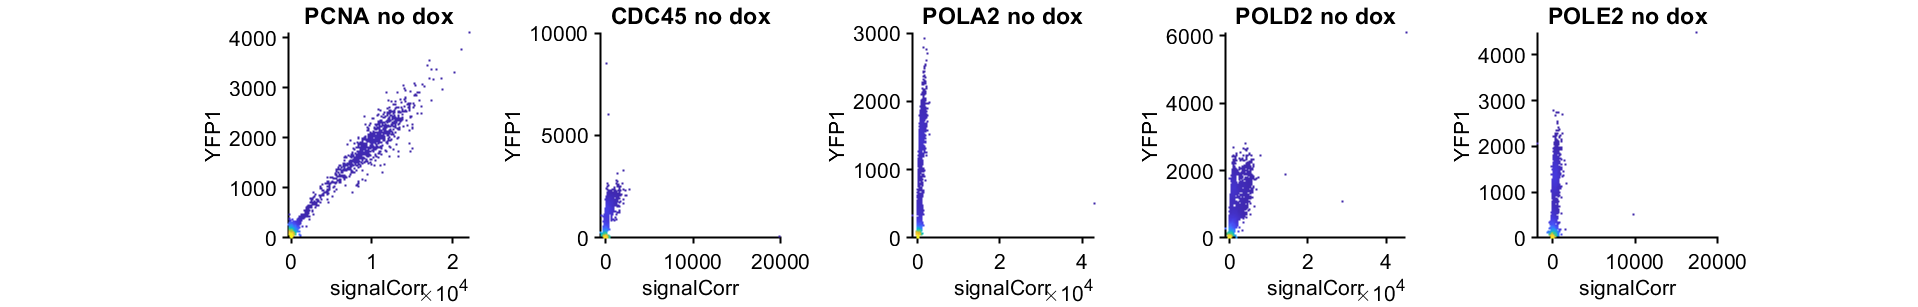

conds=[1 3 5 7 9];
f2 = figure('Units', 'Inches', 'Position', [0, 0, 5*length(conds), 4]);

for i = 1:length(conds)
    
    cond = conds(i);
    xval = 'signalCorr';
    zval = 'YFP1';
    
    xdata = S(cond).(xval);
    zdata = S(cond).(zval) - 0.0*xdata ;
   
    inds = S(cond).YFP3 < 10  & log2(S(cond).dna) < 20 & isnan(S(cond).POI(:,2));
    xdata = xdata(inds);
    zdata = zdata(inds);
   
    S(cond).pcnaCorr = S(cond).(zval) - 0 * S(cond).signalCorr;
    S(cond+1).pcnaCorr = S(cond+1).(zval) - 0 * S(cond+1).signalCorr;

    
    figure(f2)
    subplot(1,length(conds),i)
    dscatter(xdata,zdata)
    ylabel(zval);xlabel(xval);
    title(conditions(cond,1))
end

**Set thresholds based on treatment 1**

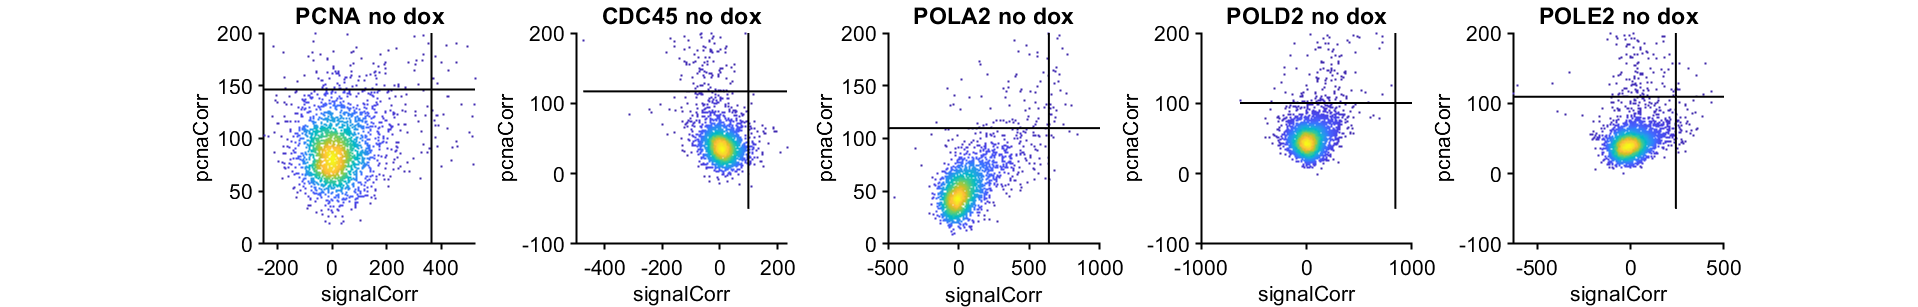

conds=[1 3 5 7 9];
f2 = figure('Units', 'Inches', 'Position', [0, 0, 5*length(conds), 4]);

for i = 1:length(conds)
    
    cond = conds(i);
    xval = 'signalCorr';
    zval = 'pcnaCorr';
    
    xdata = S(cond).(xval);
     zdata = S(cond).(zval) ;
   
    inds = log2(S(cond).dna) < 20 & isnan(S(cond).POI(:,2)) &  S(cond).YFP3 < 10 &  S(cond).eduCorr < S(cond).threshEdUCorr & S(cond).pcnaCorr < 200;
    xdata = xdata(inds);
    zdata = zdata(inds);
    
    inds = xdata < prctile(xdata, 99.5);
    xdata = xdata(inds);
    zdata = zdata(inds);
    
    S(cond).threshPCNA = prctile(zdata,95);
    S(cond).medPCNA = nanmedian(zdata);
       
    S(cond+1).threshPCNA = prctile(zdata,95);
    S(cond+1).medPCNA = nanmedian(zdata);
    
 
    figure(f2)
    subplot(1,length(conds),i)
    dscatter(xdata,zdata)
    ylabel(zval);xlabel(xval);
%     xlim([-200 1000])
%     ylim([-100 1000])
            hline(S(cond).threshPCNA,'k');vline(S(cond).threshSigCorr,'k');

    title(conditions(cond,1))
end

Settings thresholds based on 95% (with a removal of EdU positive cells by arb threshold)

**Load data into table**

conds=[1:10];
poiAligned=2;
offset=0;

dfTotal = table();

gateVals = {{},{},{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
   % ind = true(size(S(conds(i)).sigNuc(:,1))) ;
    ind = S(conds(i)).dna< 2^21 & S(conds(i)).YFP3 < 10 & S(conds(i)).pcnaCorr > S(conds(i)).threshPCNA;
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    EdU=(S(conds(i)).eduCorr(ind));
    stain=(S(conds(i)).signalCorr(ind));
    %stain=(S(conds(i)).FarRed1(ind));
   
    gates = gateVals{i};
    for j=1:length(gates)
        %gateData = S(conds(i)).(gates{j})(ind);
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        cdt1 = cdt1(inds);
        EdU = EdU(inds);
        stain = stain(inds);
    end
    
    inds = time >= 1 &  time <= 3;
    time = time(inds);
    cdt1 = cdt1(inds);
    EdU = EdU(inds);
    stain = stain(inds);
   
    cdt1(cdt1<0.0001) = .0001;
%     EdU(EdU<0.0001) = .0001;
%     stain(stain<0.0001) = .0001;
    EdUNorm = EdU./(stain);

    antibody = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    doxTreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
        phase = repmat(categorical("S"),numel(time),1);

    dfTotal = [dfTotal;table(antibody, doxTreatment,time,cdt1,EdU,stain,EdUNorm,phase)];
end


conds = 1:10;
for i=1:length(conds)
    
    ind = S(conds(i)).dna< 2^20 & S(conds(i)).YFP3 < 10  & isnan(S(conds(i)).POI(:,2)) & S(conds(i)).pcnaCorr < S(conds(i)).threshPCNA;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    EdU=(S(conds(i)).eduCorr(ind));
    stain=(S(conds(i)).signalCorr(ind));
     
    cdt1(cdt1<0.0001) = .0001;
%     EdU(EdU<0.0001) = .0001;
%     stain(stain<0.0001) = .0001;
    EdUNorm = EdU./(stain);
    
    time = repmat(0,numel(cdt1),1);
    antibody = repmat(categorical(conditions(conds(i),7)),numel(cdt1),1);
    doxTreatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
            phase = repmat(categorical("G1"),numel(time),1);

    dfTotal = [dfTotal; table(antibody, doxTreatment,time,cdt1,EdU,stain,EdUNorm,phase)];
end

dfTotal.treatment = categorical(strcat(string(dfTotal.antibody),{'\'},string(dfTotal.doxTreatment)));



Subset based on cdt1 expression

dfGated = dfTotal((log2(dfTotal.cdt1) > 8  & log2(dfTotal.cdt1) < 14 & dfTotal.doxTreatment == 'Dox+') |...
    dfTotal.doxTreatment == 'Dox-' ,:);


**comparing ND-Cdt1 expression on EdU linear fit**

ans = 676

ans = 734

slopes =    74.0975    5.4275


ratio_int =    12.5995   14.5674


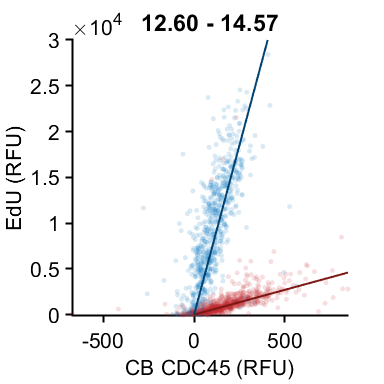

ans = 935

ans = 823

slopes =    51.7723    4.8420


ratio_int =     9.9787   11.4719


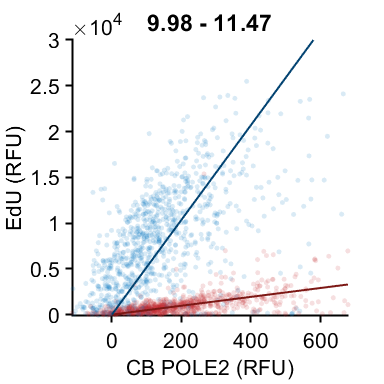

ans = 778

ans = 1235

slopes =    20.2060    2.7651


ratio_int =     6.4636    8.2241


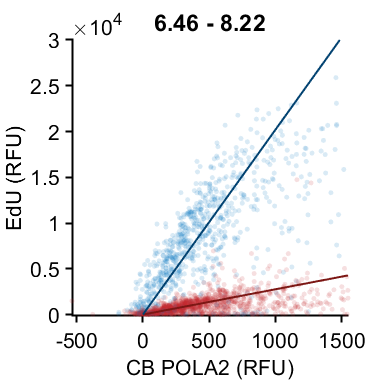

ans = 855

ans = 908

slopes =    16.2738    3.0216


ratio_int =     5.1114    5.6229


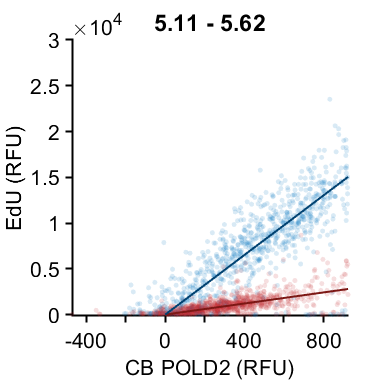

ans = 866

ans = 717

slopes =     1.2525    0.2671


ratio_int =     4.3076    4.9215


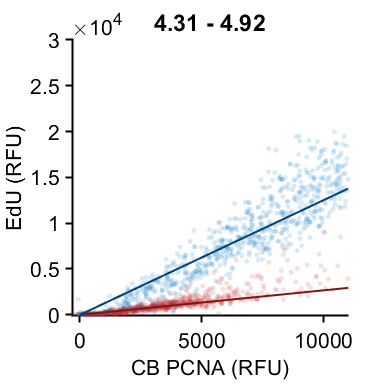

conds={'Dox-','Dox+'};
colors = [0 113 188; 193 39 45]/255;
lincol = [0 65 112; 124 23 20]/255;
colorval = [1 2];
alphas = [.15, .15];

stains = {'CDC45','POLE2','POLA2','POLD2','PCNA'};

xoffset = [10 10 50 50 200];
maxx = [250 625 1250 1000 12500];
minx = [-25 -60 -100 -200 -200];

ratios = [];
for s=1:length(stains)
    figure('Units', 'Inches', 'Position', [0, 0,4, 4]);
    hold on
    stain_name = stains{s};
    slopes = [];
    xvals = [];
    yvals = [];
    cols = [];
    p=[];
    bs = [];
    %%% Load data into new table
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain_name ,:);
        data = data(data.doxTreatment == conds{i} & data.phase == "S",:);
        xdata = (data.stain);
        ydata = (data.EdU);
        
        if strcmp(stain_name,'POLD2')
            ydata = ydata(xdata < 1000);
            xdata = xdata(xdata < 1000);
        end
        warning('off')
        b = bootstrp(10,@(x,y)robustfit(x,y,'bisquare',2,'off'), xdata,ydata);
        bs(:,i) = b;
        slopes(i) = robustfit(xdata,ydata,'bisquare',2,'off');
        warning('on')
        inds = xdata < prctile(xdata,99);
        sum(inds)
        if sum(inds) > 2000
            inds = find(inds);
            inds = randsample(inds,2000,false);
        end
%         length(inds)
        xvals = [xvals;xdata(inds)];
        yvals = [yvals; ydata(inds)];
        cols = [cols; repmat(colors(colorval(i),:),length(inds),1)];
        minstain = min(xdata(inds));
        maxstain = max(xdata(inds));
        p(i) = plot([0 maxstain],slopes(i)*[0 maxstain],'Color',lincol(i,:));

    end
    reorder = randperm(length(xvals));
    scatter(xvals(reorder),yvals(reorder),15,cols(reorder,:),'filled','MarkerFaceAlpha',alphas(i))        
    uistack(p,'top')
%     uistack(p(2),'top')

    axis square
    xlabel(['CB ' stain_name ' (RFU)'],'FontSize',16)
    ylabel('EdU (RFU)','FontSize',16)

    ylim([min(ydata)-100 30000])

%     xlim([ minx(s) maxx(s)])
xlim([minstain maxstain])

    slopes
    ratios(s) = slopes(1)/slopes(2);
    
    ratio_int = prctile(bs(:,1)./bs(:,2),[2.5 97.5])

    title(sprintf('%.2f - %.2f',ratio_int(1),ratio_int(2)))
%     
%     ratios(s) = ratio;
%     print_pdf([pwd() '\Figs_new\linear_fit_compare_' stains{s} '.pdf'])

end

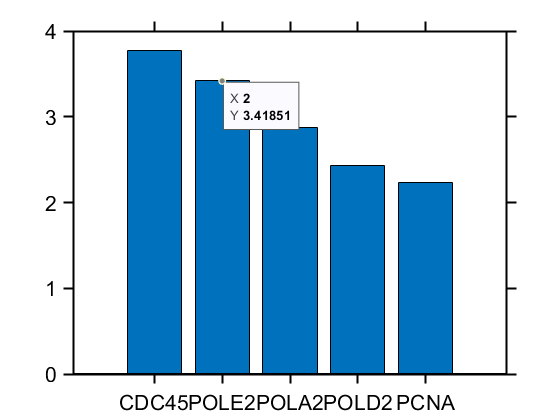


figure,
bar(log2(ratios))
hline(0,'k:')
xticklabels(stains)

writematrix(ratios)

**comparing ND-Cdt1 expression on Cdc45 and EdU**

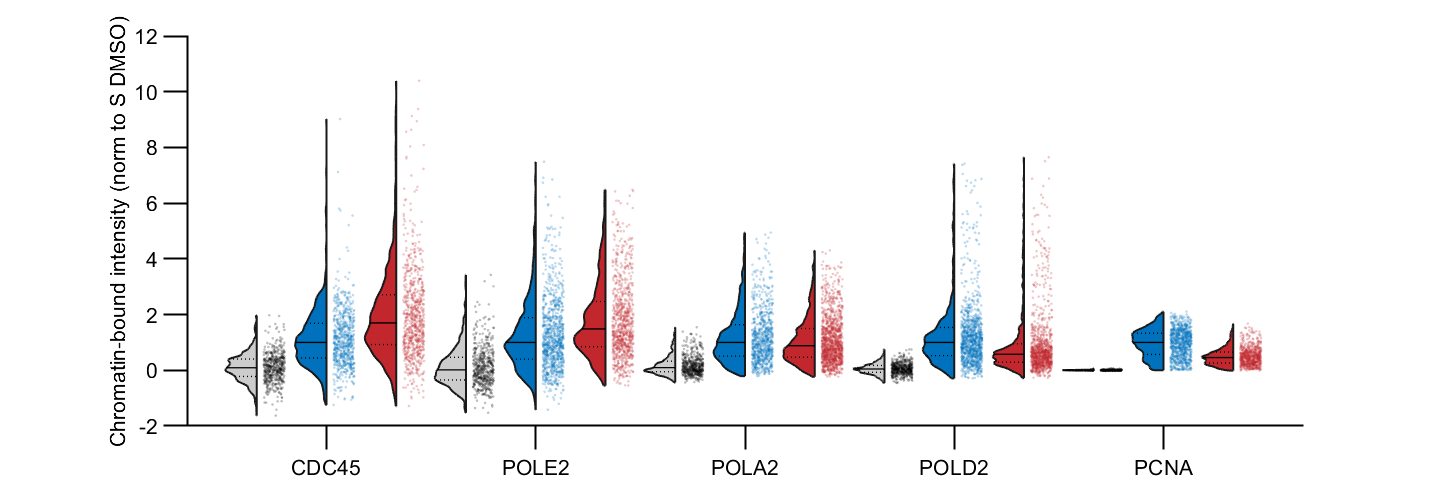

conds={'G1','Dox-','Dox+'};
colors = [0 113 188; 193 39 45]/255;
colorval = [1 2];
stains = {'CDC45','POLE2','POLA2','POLD2','PCNA'};
ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),2);
for j = 1:length(stains)
    stain = stains{j};
     stand = median(dfGated.stain(dfGated.antibody == stain & dfGated.doxTreatment == 'Dox-'& dfGated.phase == "S"));
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain,:);
        if strcmp(conds{i},'G1')
            data = data(data.doxTreatment == "Dox-" & data.phase == "G1",:);
            
        else
            data = data(data.doxTreatment == conds{i} & data.phase == "S",:);
        end
        xdata = data.stain/stand;
        
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
        if strcmp(conds{i}, 'G1')
            xdata = randsample(xdata,500,false);
        end
        
        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(conds{i}, 'Dox-')
            outmat(j,1) = median(xdata);
        elseif strcmp(conds{i},'Dox+')
            outmat(j,2) = median(xdata);
        end
    end
    
end

names = repmat({'G1','DOX-','DOX+'},1,5);
cols = repmat({[.8 .8 .8],colors(1,:),colors(2,:)}',5,1);
groupcol = repmat([0 0 0; colors([1 2],:)],5,1);

figure('Units', 'Inches', 'Position', [0, 0, 15, 5])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'Chromatin-bound intensity (norm to S DMSO)'])
xticks([2 5 8 11 14])
xticklabels(stains)
% ylim([-.75 8])
% xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\stain_compare_all.pdf'])


figure,
g.draw();

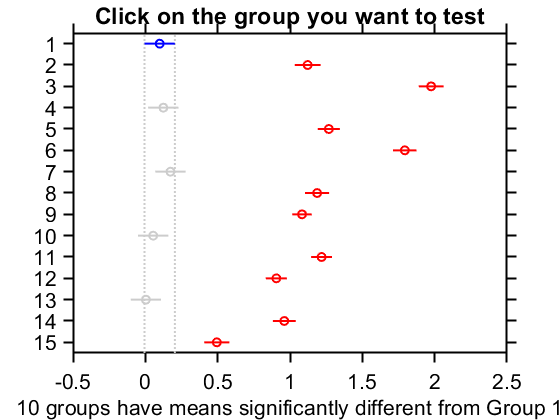

[~,~,stats] = anova1((ally),group,'off');
cdc45PostHoc = multcompare(stats);

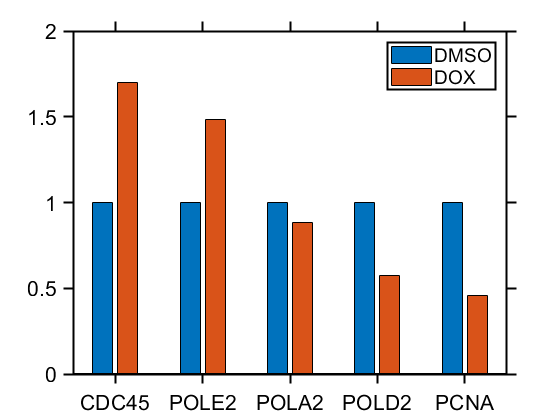


figure,
bar(outmat)
xticklabels(stains)
legend({'DMSO','DOX'})

writematrix(outmat)

**comparing ND-Cdt1 expression on Cdc45 and EdU**

conds={'Dox-','Dox+'};
colors = [0 113 188; 193 39 45]/255;
colorval = [1 2];
stains = {'CDC45','POLE2','POLA2','POLD2','PCNA'};
ally = [];
group = [];
index = 0;
outmat = NaN * ones(length(stains),2);
for j = 1:length(stains)
    stain = stains{j};
    stand = median(dfGated.stain(dfGated.antibody == stain & dfGated.doxTreatment == 'Dox-' & dfGated.phase == "S"));
    for i=1:length(conds)
        data = dfGated(dfGated.antibody == stain,:);
        data = data(data.doxTreatment == conds{i} & data.phase == "G1" & data.EdU < 100,:);

%         xdata = data.stain;       
        xdata = data.stain/stand;
        
        inds = xdata < prctile(xdata,99.5) & xdata > prctile(xdata,.5);
        xdata = xdata(inds);
        
            xdata = randsample(xdata,1000,false);
        
        
        index = index + 1;
        ally = [ally; xdata];
        group = [group; (index)*ones(size(xdata))];
        
        if strcmp(conds{i}, 'Dox-')
            outmat(j,1) = median(xdata);
        elseif strcmp(conds{i},'Dox+')
            outmat(j,2) = median(xdata);
        end
        length(xdata)
    end
    
end

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

ans = 1000

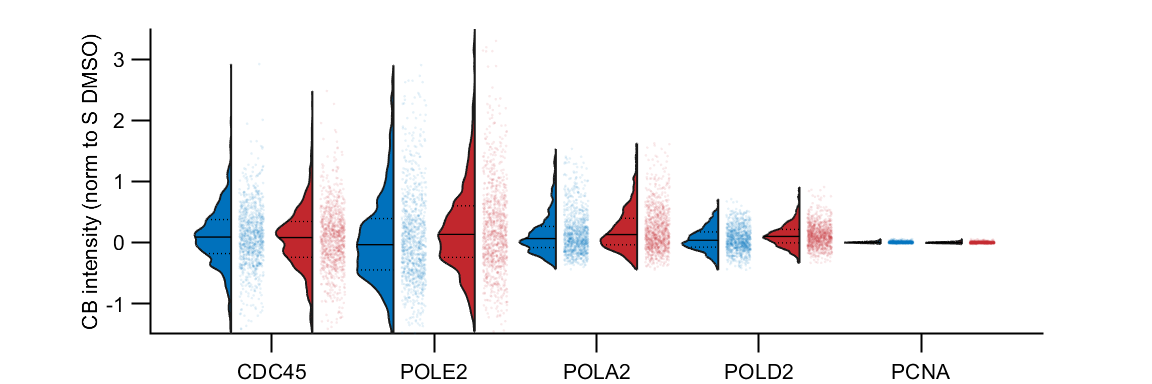


% names = repmat({'G1','DOX-','DOX+'},1,5);
cols = repmat({colors(1,:),colors(2,:)}',5,1);
groupcol = repmat([colors([1 2],:)],5,1);

figure('Units', 'Inches', 'Position', [0, 0, 12, 4])
% h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
%     'xNames',names);
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'CB intensity (norm to S DMSO)'])
xticks([1 3 5 7 9]+.5)
xticklabels(stains)
ylim([-1.5 3.5])
% xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\stain_compare_all_G1.pdf'])